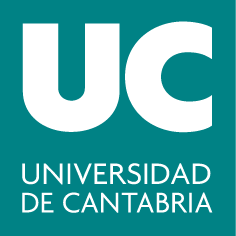

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 7: Integrales de Superficie de Campos Vectoriales**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Utilizar representaciones gráficas como apoyo para entender las definiciones y las propiedades de la integral de superficie de campos vectoriales.

- Hallar el el flujo de un campo vectorial a través de una superficie e interpretar su signo, relacionándolo con la posición relativa de los vectores del campo campo respecto a los vectores perpendiculares a la superficie.

### Resumen teórico

#### Diferencial de superficie

Se define el elemento $dS$ como un parche infinitesimal de superficie, cuya proyección sobre los planos coordenados en cada punto es:


$$dS= \frac{dxdy}{|cos (\gamma)|}=\frac{dydz}{|cos (\alpha)|}=\frac{dxdz}{|cos (\beta)|}$$


siendo $(cos(\alpha), cos(\beta), cos(\gamma))$ los cosenos directores del vector normal a la superficie en dicho punto.

Los cosenos directores se relacionan con el módulo del vector normal al plano tangente a la superficie en ese punto ($\vec{N}$). En particular, si usamos como plano de proyección el plano $XOY$:

$|\vec{n}\cdot \vec{k}|=|cos(\gamma)|$, donde $\vec{n}=\frac{\vec{N}}{| \vec{N}|}$ es el vector normal unitario.

Como $\vec{N}=\pm(-f'_{x}, -f' _{y}, 1)$ y $\vec{k}=(0,0,1)$, se tiene que $|cos(\gamma)|=\frac{1}{|\vec{N}|}$

Por lo que el diferencial de superficie es: $dS=\sqrt{(f'_{x})^2 + (f'_{y})^2 +1} dxdy$

Se razona de forma análoga para los otros dos planos coordenados.

En el caso de expresar el vector de posición en forma paramétrica (p.ej. usando coordenadas cilíndricas o esféricas): $\vec{r}(u,v)=x(u,v)\vec{i}+y(u,v)\vec{j}+z(u,v)\vec{k}$

El vector normal unitario al plano tangente en un punto de la superficie y el diferencial de superficie se calculan:


$$\vec{n}=\pm\frac{\vec{r'_{u}}\times \vec{r'_{v}}}{\Big|\vec{r'_{u}}\times \vec{r'_{v}}\Big|}$$
            
$$dS=\Big|\vec{r'_{u}}\times \vec{r'_{v}}\Big| dudv$$


#### Flujo de un campo vectorial

$\text{Flujo}=\displaystyle\int\int_{S}\vec{F}\cdot \vec{n}dS$        donde $\vec{n}$ es el vector unitario perpendicular a la superficie $S$.

### Comandos útiles

#### Comandos para representaciones en el espacio

- `quiver3(X, Y, Z, U, V, W): `Dibuja los vectores escalados de componentes U, V, W con flechas que tienen su origen en los puntos de coordenadas X, Y, Z. Las matrices X, Y, Z, U, V, W deben tener el mismo tamaño. Si se añade como quinto argumento 0, los vectores que se representan no se escalan, es decir, la longitud de las flechas es el valor real del módulo de los vectores. Ejemplo:

[X,Y] = meshgrid(-2:.2:2,-1:.15:1);
Z = X.^2+Y.^2;
U=2*X; V=3*Y; W=Z;
quiver3(X, Y, Z, U, V, W)

- `surf(X,Y,Z,C)`: Representa el gráfico de superficie de la función con los colores especificados en C (este último parámetro se puede ignorar).

- `plot3(X, Y, Z, S)`: Dibuja las curvas o el conjunto de puntos (X,Y,Z) donde X, Y y Z son vectores fila y S son las opciones de dibujo (este último parámetro se puede ignorar). 

- `view(az, el)`: Controla el punto de vista de una representación con diferentes parámetros. Sitúa el punto de vista de la figura en el indicado por los ángulos az (azimutal) y el (ángulo de elevación sobre el plano z=0), expresados en grados. view(2) ó view(0,90) sirven para recuperar la vista en 2-D.

#### Comando para crear matrices especiales

- `zeros(M, N)`: Crea una matriz MxN formada por ceros. Ejemplo: 

a = linspace(0, 2*pi, 6);
zeros(size(a)) % matriz de ceros del mismo tamaño que a

- ` ones(M, N)`: Crea una matriz MxN formada por unos. Es útil para crear matrices con un valor repetido. Ejemplos: 

ones(size(a))
3*ones(size(a))

###  Ejercicios resueltos

**1. [Ejercicio 3.10 del tema] Cálculo del flujo de un campo vectorial a través de una superficie**

Sea $S$ la porción del paraboloide $z=4-x^2-y^2$ limitada entre los planos $z=0$, $y=x$, y $x=0$. Una lámina tiene la forma dada por $S$ (ver la práctica 6). Supóngase que la lámina es de un material para el cual el flujo de calor en cada punto es proporcional al gradiente de temperatura, tomando negativa la constante de proporcionalidad: $\vec{F}=-c\vec{\nabla} T$ con $c>0$. 

a) Halla el flujo de calor hacia la cara exterior de la lámina anterior con la función temperatura $T(x,y,z)=x^2+y^2$.

b) Representa gráficamente sobre la superficie $S$ una muestra de los vectores de $\vec{F}$, así como los vectores perpendiculares a dicha superficie, tomando $c=1$. 

a) Halla el flujo de calor hacia la cara exterior de la lámina anterior con la función temperatura $T(x,y,z)=x^2+y^2$.

El campo vectorial (con $c=1$) es: $\vec{F}=-\vec{\nabla}T=(-2x, -2y, 0)$

Para plantear las integrales de superficie hay que hallar el diferencial de superficie y el vector normal unitario:

$z=f(x,y)=4-x^2-y^2$ Ecuación explícita de $S$.

$f'_{x}=-2x$        $f'_{y}=-2y$  El vector $\vec{N}$ saliente es: $\vec{N}=(-f'_{x},-f'_{y},1)=(2x, 2y, 1)$

Proyectando sobre el plano $XOY$: $dS=\sqrt{1+(f'_{x})^{2}+(f'_{y})^{2}}dxdy=\sqrt{1+4x^2+4y^2}dxdy$


$$\vec{F}\cdot \vec{n}dS=(-2x, -2y, 0)\cdot \frac{(2x,2y,1)}{\sqrt{1+4x^2+4y^2}}\sqrt{1+4x^2+4y^2}dxdy=(-4x^2-4y^2)dxdy=-4(x^2+y^2)dxdy$$


Considerando los planos que limitan $S$ y pasando a coordenadas polares, la proyección de $S$ en el plano $XOY$ es:


$$D=\lbrace (r, \theta) / 0\leq r \leq 2, \frac{\pi}{4} \leq \theta \leq \frac{\pi}{2} \rbrace$$


Por lo tanto, la integral de superficie que da el flujo es:


$$\text{Flujo}=\displaystyle\int\int_{S}\vec{F}\cdot \vec{n}dS=\int_{\pi/4}^{\pi/2}\int_{0}^{2} -4r^2 rdr d\theta=\int_{\pi/4}^{\pi/2}\int_{0}^{2} -4r^3dr d\theta$$


syms u v
flujo=int(int(-4*v^3,v,0,2),u,pi/4,pi/2)

b) Representa gráficamente sobre la superficie $S$ una muestra de los vectores de $\vec{F}$, así como los vectores perpendiculares a dicha superficie, tomando $c=1$.

t=linspace(pi/4,pi/2,10);
r=linspace(0,2,20);
[T,R]=meshgrid(t,r);
X=R.*cos(T); Y=R.*sin(T);
Z=4-X.^2-Y.^2;
surf(X,Y,Z,X.^2+Y.^2) % cuarto argumento color con el valor de T=X^2+Y^2
xlabel('x')
ylabel('y')
zlabel('z')
shading interp
view([38,27])
title('paraboloide z=4-x^2-y^2 coloreado según T=x^2+y^2')
axis equal
hold on
%Dibuja una muestra del campo vectorial E=(-2x,-2y,0) sobre S
% escalado, en rojo
quiver3(X,Y,Z,-2*X,-2*Y, zeros(size(X)),'r');
 
% Representa vectores normales a la superficie, hacia arriba, 
% N=(2x,2y,1), escalado, en negro
quiver3(X,Y,Z,2*X,2*Y,ones(size(X)),'k');
hold off

La componente normal del campo $\vec{F}$ en la dirección del vector normal $\vec{n}$ tiene signo opuesto, lo que justifica el valor del flujo resultante. 